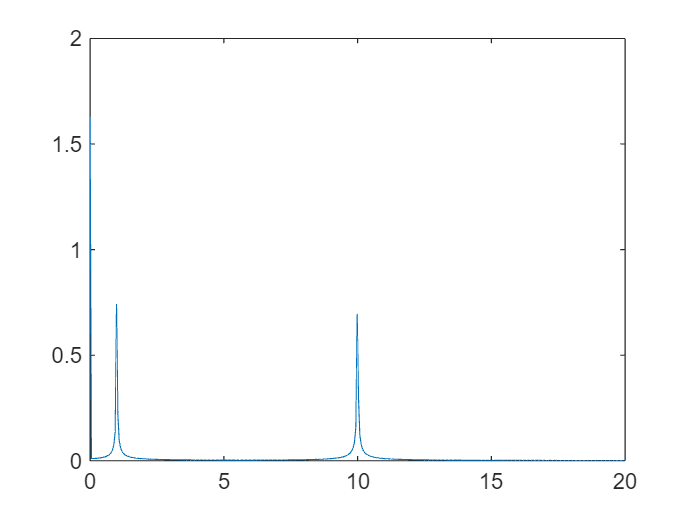

clear all
T = readtable('fft_data.csv');
y = T{:,1};
fs = 100;
dt = 1/fs;
t = [0:dt:length(y)*dt-dt];

Y = abs(fft(y))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:floor(end/2));
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:floor(end/2));
plot(f_egy,Y_egy)
xlim([0,20])

clear all
f1 = 1;
f2 = 10;
T = readtable('adcData.csv');
%%y = T{1:1865,2};
y = T{1:200,5};
fs = 100;
dt = 1/fs;
t = [0:dt:length(y)*dt-dt];
plot(t,y);

%least square method
n = length(y);
D = [cos(2*pi*f1*t)',sin(2*pi*f1*t)',cos(2*pi*f2*t)',sin(2*pi*f2*t)', ones(n,1)]; %trig identity to cos + sin for phase
DD = D'*D;
DD_inv = inv(DD);
K = DD\D'*y % least square

K =    -0.8118
   -0.0255
    0.2505
   -0.7709
    1.6245


R1_est = sign(K(1))*sqrt(K(1)^2+K(2)^2)

R1_est = -0.8122

R2_est = sign(K(3))*sqrt(K(3)^2+K(4)^2)

R2_est = 0.8106

fi1_est = atan(-K(2)/K(1))+pi/2 

fi1_est = 1.5394

fi2_est = atan(-K(4)/K(3))+pi/2 

fi2_est = 2.8274

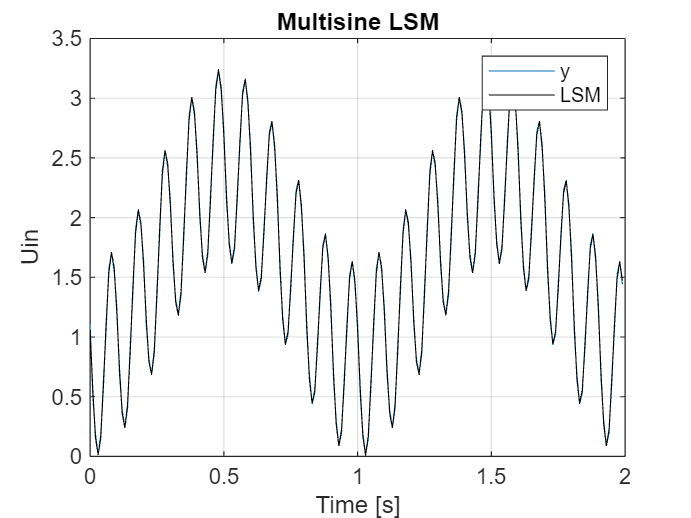


%plotting
y_est = R1_est*sin(2*pi*f1*t+fi1_est)+R2_est*sin(2*pi*f2*t+fi2_est)+K(5);
hold on;
plot(t,y_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('y','LSM')
title('Multisine LSM')